% Set up
clc;
close all;
clear;

EEG1 = cell(10,1); % create a 10 x 1 cell array
EEG2 = cell(10,1); % use EEG2{1} to visit the first matrix
EOGL = cell(10,1);
EOGR = cell(10,1);
STAGE = cell(10,1);


% load all data
for n = 1:10
    edfFilename = sprintf('R%d_edf.mat', n);
    xmlFilename = sprintf('R%d_xml.mat', n);
    load(edfFilename);
    load(xmlFilename);
    Fs = hdr.samples(3); % Since this is the biggest Frequency (125 Hz), we use it to calculate number of epochs
    Fs_EOG = hdr.samples(6);
    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    samplingPoints_EOG = numberOfEpochs*epochLength*Fs_EOG;
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);    % epochLength = 30
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    eogl = zeros(numberOfEpochs,Fs_EOG*epochLength);
    eogr = zeros(numberOfEpochs,Fs_EOG*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs_EOG*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs_EOG*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs_EOG*epochLength);
        eogl(i,:) = record(6, epochStart:epochEnd);
        eogr(i,:) = record(7, epochStart:epochEnd);
    end
    EEG1{n} = eeg1;
    EEG2{n} = eeg2;
    EOGL{n} = eogl;
    EOGR{n} = eogr;
    % process the stages
    stages_epoch = zeros(numberOfEpochs,1);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE{n} = stages_epoch;
    STAGE{n}(STAGE{n} == 1) = 2;
end

% It will filter every row
EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);
[EOGL_filtered, EOGR_filtered] = preprocess_eog(EOGL, EOGR, Fs);

EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

% Extract time-frequency features
features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);

% EOG features
features_EOGL=extract_EOG_features(EOGL_filtered);
features_EOGR=extract_EOG_features(EOGR_filtered);

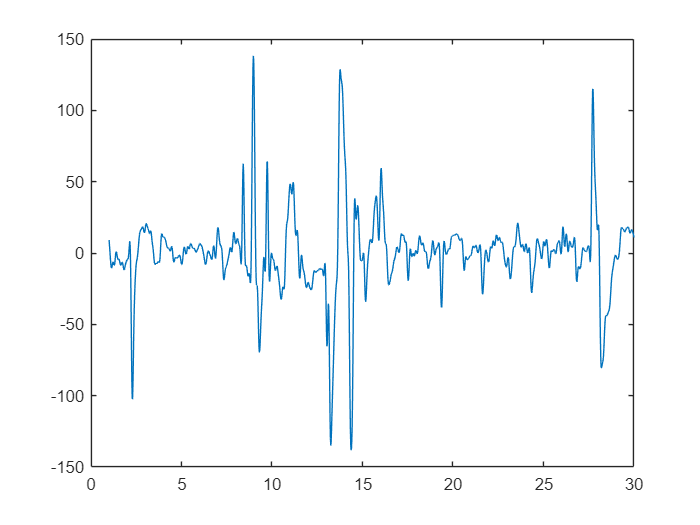

plot(linspace(1,(length(EOGL_filtered{1}(1,:))/Fs_EOG),length(EOGL_filtered{1}(1,:))),EOGL_filtered{1}(1,:))

% Append the new features to the existing feature set
features = cell(size(features_timefreq_eeg2));
for i = 1:10
    features{i} = [features_time_eeg1{i}, features_time_eeg2{i},...
                   features_freq_eeg1{i}, features_freq_eeg2{i},...
                   features_timefreq_eeg1{i},features_timefreq_eeg2{i},...
                   features_EOGL{i}, features_EOGR{i}];
    %features{i} = normalize(features{i});
end

% Data
% Assume you already have the merged feature cell array: features
% Assume you have corresponding label data: labels (each subject corresponds to one label)

numSubjects = length(features);
accuracies = zeros(numSubjects, 1); % Accuracy for each fold
all_predictions = []; % Prediction results
all_true_labels = []; % Ground truth

% LOSO (Leave-One-Subject-Out)
for i = 1:numSubjects
    % Use the i-th subject's data as the test set
    test_features = features{i};
    test_label = STAGE{i};
    
    % Use the remaining subjects' data as the training set
    train_indices = setdiff(1:numSubjects, i);
    
    % Merge training features
    train_features = [];
    train_labels = [];
    
    for j = train_indices
        train_features = [train_features; features{j}];
        train_labels = [train_labels; STAGE{j}];
    end
    
    % Optional: Feature normalization
    % Normalize using the mean and standard deviation from the training set
    mean_train = mean(train_features);
    std_train = std(train_features);
    train_features = (train_features - mean_train) ./ std_train;
    test_features = (test_features - mean_train) ./ std_train;
    
    % Train kNN model
    knn_model = fitcknn(train_features, train_labels, 'NumNeighbors', 3, 'Distance', 'euclidean');
    
    % Predict test set
    predictions = predict(knn_model, test_features);
    
    % Calculate accuracy
    correct = sum(predictions == test_label);
    total = length(test_label);
    accuracies(i) = correct / total;
    
    % Store prediction results
    all_predictions = [all_predictions; predictions];
    all_true_labels = [all_true_labels; test_label];
    
    fprintf('Accuracy with subject %d as test set: %.2f%%\n', i, accuracies(i) * 100);
end

Accuracy with subject 1 as test set: 78.86%
Accuracy with subject 2 as test set: 88.31%
Accuracy with subject 3 as test set: 82.63%
Accuracy with subject 4 as test set: 66.59%
Accuracy with subject 5 as test set: 81.26%
Accuracy with subject 6 as test set: 51.25%
Accuracy with subject 7 as test set: 65.90%
Accuracy with subject 8 as test set: 65.45%
Accuracy with subject 9 as test set: 71.06%
Accuracy with subject 10 as test set: 73.96%


%% 3. Calculate overall performance metrics
overall_accuracy = mean(accuracies);
fprintf('Average accuracy of LOSO cross-validation: %.2f%%\n', overall_accuracy * 100);

Average accuracy of LOSO cross-validation: 72.53%


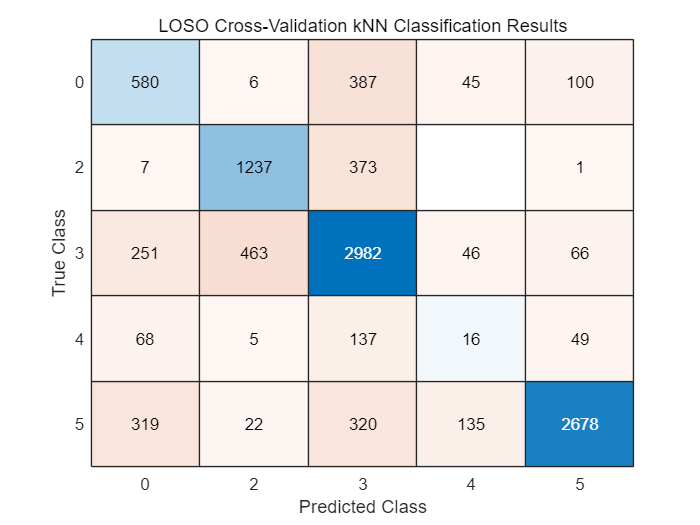

% Compute confusion matrix
cm = confusionchart(all_true_labels, all_predictions);
cm.Title = 'LOSO Cross-Validation kNN Classification Results';
cm.XLabel = 'Predicted Class';
cm.YLabel = 'True Class';


% Calculate additional metrics (if binary classification)
if length(unique(all_true_labels)) == 2
    [precision, recall, f1, specificity] = calcMetrics(all_true_labels, all_predictions);
    fprintf('Precision: %.2f, Recall: %.2f, F1-score: %.2f, Specificity: %.2f\n', ...
        precision, recall, f1, specificity);
end

